# Deriving a Fourier Approximation to the Hyperbolic Tangent

## Setup

clc; clear; close all;

## Sine Transform of $\mathrm{tanh}\left(v\right)$

The sine transform of $\mathrm{tanh}\left(v\right)$ is known to be:


$$\sqrt{\frac{2}{\pi \;}}\int_0^{\infty \;} \mathrm{tanh}\left(v\right)\mathrm{sin}\left(\zeta v\right)\;\mathrm{dv}=\sqrt{\frac{\pi }{2}}\mathrm{csch}\left(\frac{\pi \;\zeta \;}{2}\right)$$


v = -15:0.01:15;
y = tanh(v);

figure;

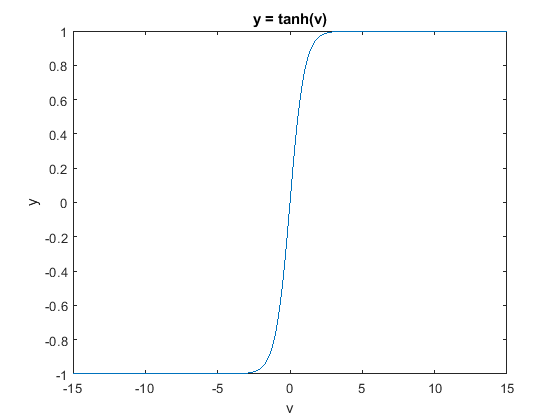

plot(v, y);
xlabel('v');
ylabel('y');
title('y = tanh(v)');

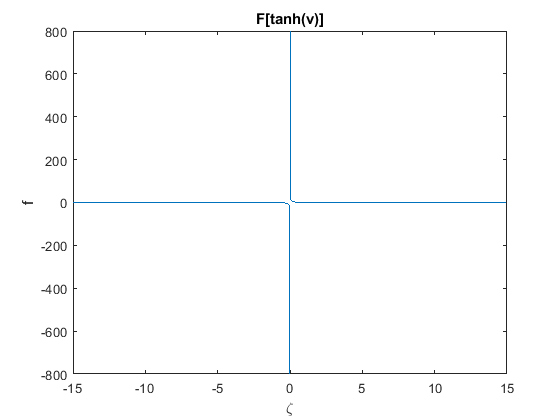

dzeta = 0.001;
zeta = -15:0.001:15;
f = sqrt(pi/2)*csch(pi*zeta/2);

figure;
plot(zeta, f);
xlabel('\zeta');
ylabel('f');
title('F[tanh(v)]');

## Try to Reconstruct $\mathrm{tanh}\left(v\right)$ from its Fourier Transform

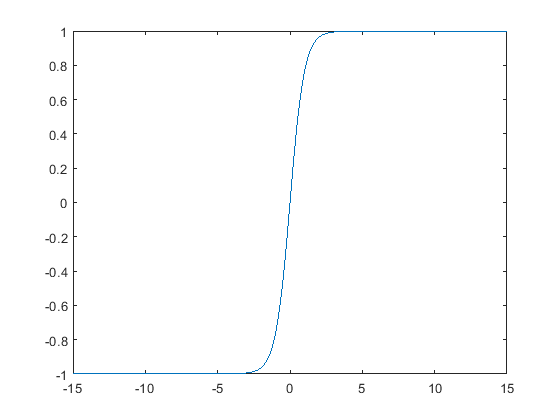

y_approx = zeros(size(v));

figure;
for i = 1:length(zeta)
    
    term = csch(pi*zeta(i)/2)*sin(zeta(i)*v);
    
    if ~(zeta(i) < eps)
        y_approx = y_approx + term;
    end
    
end

y_approx = y_approx * dzeta;

plot(v, y_approx)

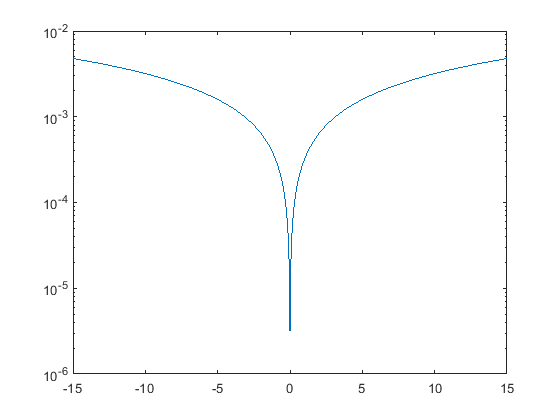

figure;
error = abs(y_approx - y);
semilogy(v,error);